# Part 2: Explore a single DNA sequence

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

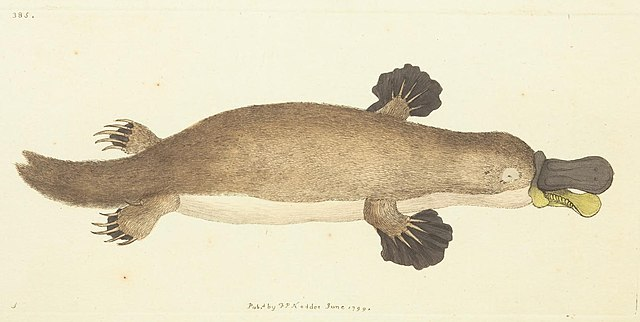

The first known illustration of a platypus, drawn by Frederick Polydore Nodder, and published in [1799](https://commons.wikimedia.org/wiki/File:Platypus_(Ornithorhynchus_anatinus)._First_Description_1799.jpg). 

Let's first play around with one example DNA strand. We'll use reference mitochondrial DNA ([mtDNA](https://en.wikipedia.org/wiki/Mitochondrial_DNA)) from a platypus. mtDNA is DNA that is located in the mitochondria (powerhouse!) of the cell. Most DNA is found in the nucleus of the cell, so mtDNA is a pretty small portion of DNA (imagine something close to 16,500 base pairs in a human as opposed to something on the order of billions when you're talking about nuclear DNA). mtDNA is interesting because it is exclusively inherited from the mother, rather than being a mixture between parents. So from generation to generation, it remains *relatively* unchanged (there are mutations, but there's no "mixing" from the father's DNA). So you can map a maternal lineage with mtDNA, which makes it possible to study even ancient populations and track things like migration. It also has a relatively high rate of mutation, and the buildup of mutations can be used as an evolutionary "clock" of sorts to determine when species diverged from one another. 

## 1: Import a sequence of platypus DNA

Let's grab our data. MATLAB® has a special function in the [Bioinformatics Toolbox](https://www.mathworks.com/help/bioinfo/)™ that will retrieve sequences from the [GenBank](https://www.ncbi.nlm.nih.gov/genbank/) database, which is run by the National Center for Biotechnology Information (NCBI). You can search around for different nucleotide sequences and get an 'accession number' which you'll use to import that data. Click on the [GenBank](https://www.ncbi.nlm.nih.gov/genbank/) link and type "platypus mtDNA" to check it out!  

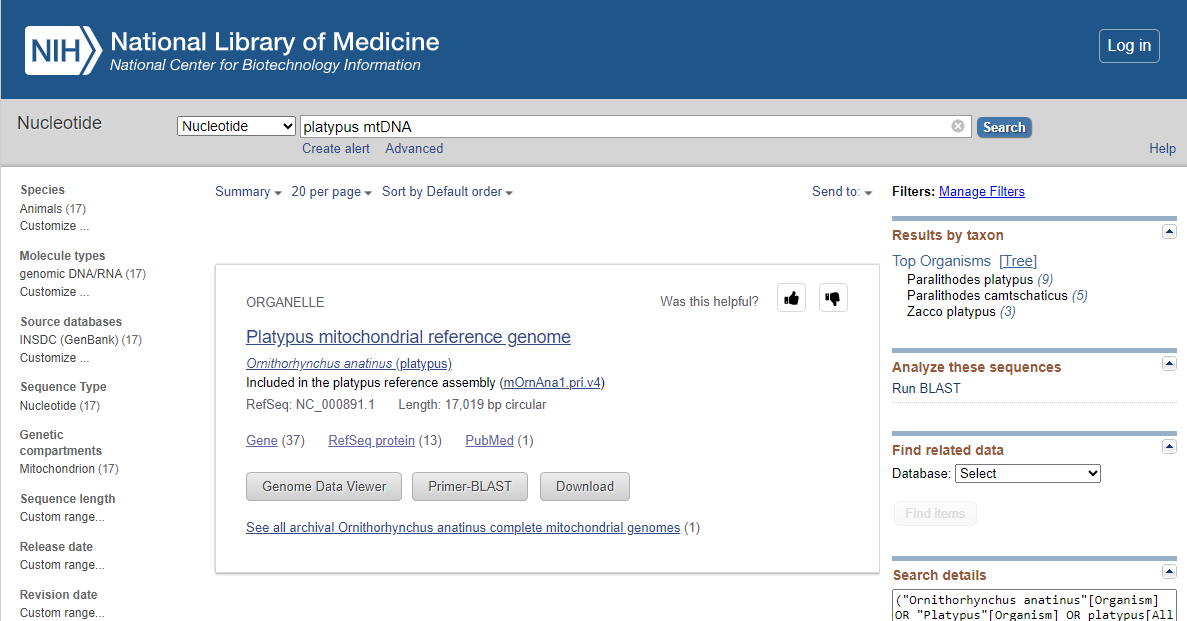

You'll see a lot of information about this species, but you can use the RefSeq number (NC_00891) to get the mitochondrial reference strand imported. Note MATLAB ignores the decimal point at the end, so you can too. 

Use the function [`getgenbank()`](https://www.mathworks.com/help/bioinfo/ref/getgenbank.html) to pull this data. We need to give the function the reference number, and then tell MATLAB to only import the mtDNA sequence itself by using the `"sequenceonly"` option. 

platypus = getgenbank("NC_000891", "sequenceonly", true) 

We now have a sequence of nucleotide bases saved as the variable `platypus`!

How long is this mtDNA sequence? 

  Type `length(platypus)` into the code block and run the section: 

~17,000 bases are easier to imagine than 3 billion, but it's still quite a lot to consider, and MATLAB can help us analyze the statistics of such a sequence! 

We can index into this sequence much like we can index into any other variable in MATLAB. 

  For example, run `platypus(1:10)` to output only the first 10 nucleotides of this sequence: 

## 2: Analyze the statistics of your sequence 

Suppose you want to know how many of each nucleotide type is in your sequence. We can count them! 

How many "G" bases do we have?

num_G = sum(platypus == 'G')

This works because `platypus == 'G' `gives an array the length of `platypus` that contains a 1 in every position where `platypus` contains a 'G', and a 0 in every position where `platypus` contains any other nucleotide. So if we sum this array of 1s and 0s, we will get the number of times a 'G' appeared in the `platypus` array.

DIY time! 

  Find the number of 'A' nucleotides in your sequence: 

We could keep this going and find the number of C and T nucleotides individually, but there are a couple of other tips and tricks we can try out instead. 

One thing we haven't covered yet in these modules that can sometimes help quite a bit in writing MATLAB code is the concept of [loops](https://www.mathworks.com/help/matlab/control-flow.html?s_tid=CRUX_topnav). Usually, we give MATLAB a command and it executes that command exactly one time. For example: 

disp("Hello there!")

prints out 'Hello there!' exactly one time. 

**An interlude on loops**

A loop (in this case, a [`for`](https://www.mathworks.com/help/matlab/ref/for.html) loop) allows you to give MATLAB a single command, but then tell it to repeat that command a specified number of times. Maybe I want my computer to say hello to me 10 times. We can do this by setting up a `for` loop that will run 10 times (`i =10`), with our instructions (`disp ('Hello there!')` inside. 

for i = 1: 10 % say how many times to repeat (10) and give this counter variable a name, i 
    disp ("Hello there!")
end % explicitly end your loop so MATLAB knows exactly what instructions are supposed to be repeated  

Another example: 

We can also use the counter variable `i` within the loop. For example, 

for i = 1:4 
    mydisplay(i) = i;
end 

mydisplay

Here, we used indexing to our advantage. Recall that if we have an array and we say `array(5)` we will pull out the 5th element of that array. This is just the reverse of that. When `i=1`, the first element of `mydisplay` (`mydisplay(1)`) becomes 1. On the second iteration of the loop (`i=2`), we have `mydisplay(2) = 2,` and so on. You can see how the output `mydisplay` reflects this iteration. 

  **Note**. The code analyzer warning (orange squiggle) is giving you advice about how to make your code better. In this case, `mydisplay` is very small so the efficiency doesn't matter. However, if you want to learn more about `for` loops you could check out [`Loops.mlx`](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Fundamentals-of-Programming&project=FundamentalsofProgramming.prj&file=Loops.mlx) in the [Fundamentals of Progamming](https://www.mathworks.com/matlabcentral/fileexchange/103225-fundamentals-of-programming) module. To understand more about the warning, you could work through the [Optimizing Your Code](https://matlabacademy.mathworks.com/details/matlab-programming-techniques/mlpr#module=4) module in the Self-Paced Online Course [MATLAB Programming Techniques](https://matlabacademy.mathworks.com/details/matlab-programming-techniques/mlpr).

### Count nucleotides

So, to count all the nucleotides, you could use a for loop! First, let's figure out what nucleotides we have in our sequence (we expect A, T, C, G). One way to do this would be by asking MATLAB to give us the values that appear in our sequence by using the [`unique()`](https://www.mathworks.com/help/matlab/ref/double.unique.html) function. This function tells you every value that appears in an array, but only prints each value out once, regardless of how many times it appears. 

nucl = unique(platypus)

Cool, that's just what we expected! So given our variable `nucl`, we can find the number of 'G' bases in a different way. 'G' is the third element of `nucl` (i.e. `nucl(3)`). So we can set this equal to platypus to find the number of positions where platypus contains a 'G'. 

  Type 

into the cell block to determine how many Gs are in the sequence. 

Now let's loop.

We will pre-allocate the array `count`. Because we are adding one value to this array each time the loop runs, `count` changes size on each iteration if we don't pre-allocate it (make an array of the correct size but fill it with zeros or NaNs). It's good practice to pre-allocate so that you don't have an array that changes size on each loop iteration. This loop goes through `nucl` one element at a time and finds the number of that nucleotide in the sequence. On the first iteration of the loop, for example, i=1, `nucl(1)`= 'A', so `count(1)` is the number of times 'A' appears in the sequence, and so on. 

count = zeros(1,4); % pre-allocate your size!
for i = 1:4  % Because there are 4 nucelotides, we need to run the code 4 times
    count(i) = sum(platypus == nucl(i)); 
end 

count % look at count

The values of G and A here are the same as what we calculated before, but implementing a loop is much faster than calculating each nucleotide individually. We've now learned how basic loops in MATLAB can make our data analysis a little bit cleaner and faster. While it's extremely worthwhile to think about loops and ways to implement this code yourself, sometimes MATLAB has tricks to make our lives easier. In this case, the [Bioinformatics Toolbox](https://www.mathworks.com/help/bioinfo/) has a function that can do this base counting for us! 

Try out [`basecount()`](https://www.mathworks.com/help/bioinfo/ref/basecount.html)`:`

bases=basecount(platypus)

`bases` is a [structure array](https://www.mathworks.com/help/matlab/ref/struct.html), which is a data type we haven't encountered before. In a structure array, data is saved into 'fields', which in this case are named A, C, G, and T. You can access data in a field by using ['dot notation'](https://www.mathworks.com/help/matlab/creating_plots/access-and-modify-property-values.html). To learn more about structure arrays, you could check out [`StoringData.mlx`](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Programming-Organizing-Data&project=OrganizingData.prj&file=StoringData.mlx) in the [Programming: Organizing Data](https://www.mathworks.com/matlabcentral/fileexchange/115900-programming-organizing-data) module.

  For example, try accessing the A field by typing `bases.A` in the code box and running the section: 

Change the field to access different values within bases. 

### Plot nucleotide content 

You can also pass an input to `basecount()` to get it to make a pie chart of your nucleotide numbers: 

basecount(platypus,"Chart","pie")

  For fun, try changing "pie" to "bar". 

The Bioinformatics Toolbox also contains a function called [`ntdensity()`](https://www.mathworks.com/help/bioinfo/ref/ntdensity.html) which plots the density of a nucleotide over a sequence. The goal of plotting a density function like this is to understand how data is distributed overall.

At any given point in the sequence, take, for example, sequence position 1000, a 'window' of a given size is placed around that data point. In this instance, the window size is about 850 (because the default window size is `length(platypus)/20). `So the function looks at the 850 sequence positions surrounding your given sequence point (the window is centered on point 1000, and looks at values both before and after that point, so it would be looking at the 425 positions on each side) and counts up the number of each nucleotide in that chunk of sequence. This allows us to see how the nucleotides are distributed throughout the sequence. This is done for every value in the sequence and plotted as below (if you are at an early or late position in the sequence where there aren't 425 positions available in either direction, the window is truncated to whatever size fits). 

  Type `ntdensity(platypus)` below and run this section: 

In the first 1000 values of the sequence, there are about 18% Gs, 22% Cs, 25% Ts, and 35% As. Oftentimes, [GC content](https://en.wikipedia.org/wiki/GC-content)  (which at position 1000 is about 40%), is a measure used to describe DNA and means the amount of Gs and Cs in your sequence. This type of chart allows you to see the GC content. In this case, AT content is much higher than GC content. 

 GC content is interesting because Gs and Cs affect the stability of the DNA double helix, so it can be a measure of stability. The G-C bond is stronger than the A-T bond due to the number of [hydrogen atoms involved](https://en.wikipedia.org/wiki/GC-content) (there are more between G and C and more means more stable). GC content has been and continues to be highly studied. It's been suggested that GC-rich genes have unique features and purposes (two articles of interest: [1](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC152811/), [2](https://bmcresnotes.biomedcentral.com/articles/10.1186/s13104-019-4137-z)), but a definitive conclusion is still up in the air. It also tends to vary significantly across organisms, so can be used in taxonomy! 

What else can we do with this sequence? 

## 3: Transcribe your DNA sequence 

We know for example that DNA sequences are [transcribed](https://en.wikipedia.org/wiki/Transcription_(biology)) to RNA. Can we do this in MATLAB? 

Recall that DNA is used to synthesize complementary RNA (a template strand of DNA synthesizes a complementary RNA strand), which then can serve as a template for protein synthesis. 

Suppose our platypus DNA is a synthesis strand. Let's construct the complementary RNA strand (messenger RNA). For transcription, the base pairing rules are A-U (instead of T, thymine, we have U, uracil, in RNA sequences) and G-C. 

Let's define our DNA nucleotides: 

DNAbases = ['A', 'T', 'C', 'G']; 

In the case of the mRNA, where there is an A in the DNA, we'll have a U in the complementary RNA. Where there is a T in the DNA, we'll have an A in the RNA, where there is a C in DNA we have a G in the RNA, and so on. 

  Type

in the code block. The order of the DNA and RNA matters! Position 1: A-U Position 2: T-A Position 3: C-G Position 4: G-C. Make sure your pairs match.

The function [`changem()`](https://www.mathworks.com/help/map/ref/changem.html) lets us replace values in a vector. The first input is the array platypus, and then the second input is the "new" values, and the third output is the "old values". The new values are the RNA values, and the old values are the current values of platypus or the DNA nucleotides. Running this code will create an array where all As become Us, all T's become As, all Cs become Gs, and all Gs become Cs:

mrnaPlatypus = changem(platypus, RNAbases, DNAbases)

Now we've explored a single DNA strand and simulated transcription using MATLAB. Now that we've played around with a single strand of DNA and now what that looks like imported into MATLAB, we can look at DNA across multiple species of mammals. For more ways to calculate sequence statistics in MATLAB, check out this resource: [Calculating and Visualizing Sequence Statistics - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/bioinfo/ug/calculating-and-visualizing-sequence-statistics.html)

[*Go to next section (Comparative genetics)*](matlab: edit S3_Comparative_genetics.mlx)

[*Return to introduction*](matlab: edit S1_Introduction.mlx)